# Solving Nonlinear Systems of Equations (using Symbolic Math Toolbox)

## Grant Eyer 

## CME 220

#### This is an chemical engineering application for solving a set of nonlinear equations for a chloroform(1) + ethanol(2) binary system. The nonlinear system that will be used to solve this problem is shown below.


$$\begin{array}{l}
\mathrm{Total}\;\mathrm{Material}\;\mathrm{Balance}:20=\dot{L} +\dot{V} \\
\mathrm{Chloroform}\;\mathrm{Material}\;\mathrm{Balance}:4=x_1 \dot{L} +y_1 \dot{V} \\
{\mathrm{Chloroform}\;\mathrm{Modified}\;{\mathrm{Raoult}}^{\prime } s\;\mathrm{Law}:\;y}_1 P=\gamma_1 x_1 P_1^{\mathrm{sat}} \\
\mathrm{Chloroform}\;\mathrm{Modified}\;{\mathrm{Raoult}}^{\prime } s\;\mathrm{Law}:\left(1-y_1 \right)P=\gamma_2 \left(1-x_1 \right)P_2^{\mathrm{sat}} 
\end{array}$$


#### Where:

-  $P_1^{\mathrm{sat}}$ and $P_2^{\mathrm{sat}}$ are the pure component vapor pressures for chloroform and ethanol, respectively.

-  
$$\gamma_1 =\exp \left({A\left(x_2 \right)}^2 \right)$$
 

-  
$$\gamma_2 =\exp \left({A\left(x_1 \right)}^2 \right)$$
 

#### Notes about nonlinear system:

-  $P_1^{\mathrm{sat}}$ and $P_2^{\textrm{sat}}$ will have been previously determined for chloroform and ethanol and will therefore be treated as constants.

- $\gamma_1$ and $\gamma_2$ represent the activity coefficients for chloroform and ethanol, respectively. The equations that are used to estimate these values comes from the 1-Margules equation.

#### Relevant Information/Equations used: 

The Antoine equation is used to estimate $P_i^{\textrm{sat}}$:


$$\log_{10} \left(P_i^{\textrm{sat}} \right)=A-\frac{B}{T+C}$$


Where

- $A$, $B$, and $C$ are parameters that fit the pure component vapor pressure data

- $T$ is the boiling point of the pure component (in Celsius)

- $P_i^{\textrm{sat}}$ is the pure component vapor pressure (in mmHg)

Modified Raoult's Law equation is defined as:


$$y_i P=\gamma_i x_i P_i^{\textrm{sat}}$$


Where 

- $y_i$ is the vapor mole fraction of component $i$

- $P$ is the system pressure

- $\gamma_i$ is the activity coefficient of component $i$

- $x_i$ is the liquid mole fraction of component $i$

- $P_i^{\textrm{sat}}$ is the pure component vapor pressure of component i.

The experimental value of $\frac{{\underline{G} }_E }{\textrm{RT}}$ based on experimental data can be found by the below formula:


$$\frac{{\underline{G} }_E }{\textrm{RT}}=x_1 \ln \left(\gamma_1 \right)+x_2 \ln \left(\gamma_2 \right)$$


Where 

- $x_1$ and${\;x}_2$ represent the compositions of chloform and ethanol in the liquid phase, respectively.

- $\gamma_1$and $\gamma_2$ represent the activity coefficients of chloform and ethanol in the liquid phase, respectively

-  $\frac{{\underline{G} }_E }{\textrm{RT}}$  is the excess property of the chloroform(1) + ethanol(2) mixture (${\underline{G} }_E$)  divided by Temperature (T) and the gas constant ($R$). 

The 1-Margules equation is defined as follows:


$$\frac{{\underline{G} }_E }{\textrm{RT}}=Ax_1 x_2$$


Where 

-  $\frac{{\underline{G} }_E }{\textrm{RT}}$  is the excess property of the chloroform(1) + ethanol(2) mixture (${\underline{G} }_E$)  divided by Temperature (T) and the gas constant ($R$). 

- $A$ is the 1-Margules equation parameter.

- $x_1$ and${\;x}_2$ represent the compositions of chloform and ethanol in the liquid phase, respectively.

The activity coefficients can be determined from the 1-parameter Margules equation as:


$$\ln \left(\gamma_1 \right)={A\left(x_2 \right)}^2$$
  


$$\ln \left(\gamma_2 \right)={A\left(x_1 \right)}^2$$


Where

- $x_1$ and${\;x}_2$ represent the compositions of chloform and ethanol in the liquid phase, respectively.

- $\gamma_1$and $\gamma_2$ represent the calculated activity coefficients for chloform and ethanol in the liquid phase, respectively

#### Flash Calculation Problem Description:

20 mol/min of a mixture of mixture containing 20 mole % chloroform and 80 mole % ethanol at 

T = 332.4 K and P = 101.3 kPa and flows into a flash container at T = 332.4 K and P = 70 kPa. The problem requires 

that I use the 1-Margules activity coefficient method to find the outlet vapor and liquid feed stream molar flow rates and 

compositions.

### Flowchart for problem 

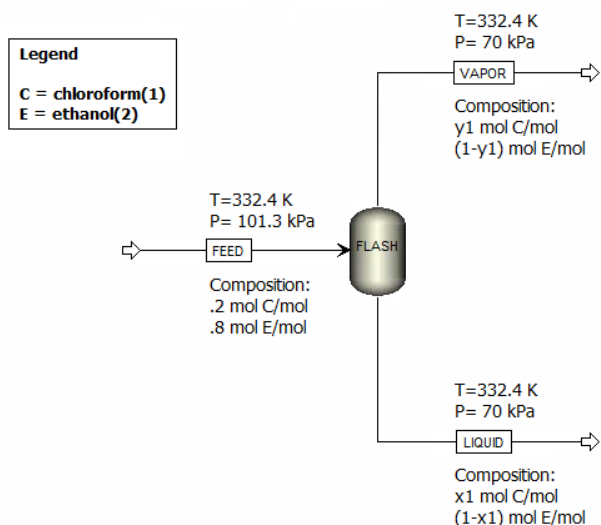

Define the temperature to be 59.25 C (which is 332.4 K). The temperature needs to be converted to Celsius so that the Antoine equations can be used.

Temperature = 332.4-273.15;

Define the pressure of the system to be 101.3 kPa

Pressure = 101.3;

Based on experimental data, the azeotrope of the chloroform(1) + ethanol(2) system was determined to be around $x_1$ = .84. 

azeotrope = .84;

Estimate the vapor pressure of chloroform and ethanol by using the Antoine parameters from *Fundamentals of Chemical Engineering Thermodynamics *by Dahm and Visco. 

In Appendix E, the Antoine parameters for chloroform are $A$= 6.4934, $B$= 929.44, and $C$= 196.03; the Antoine parameters for ethanol are  $A$=8.32109 , $B$= 1718.10, and $C$= 237.52.

Convert these pressures from mmHg to kPa.

P1sat = 10^(6.4934-929.44/(Temperature+196.03))*(101.325/760);
P2sat = 10^(8.32109-1718.10/(Temperature+237.52))*(101.325/760);

Find the $\gamma$ values by divding the system pressure by vapor pressures of each component. Use those values to then determine the $A$ value for the 1-parameter Margules equation.

Display the$A$ value for the 1-paramter Margules equation.

gammaAz = Pressure./[P1sat,P2sat];
A=(azeotrope*log(gammaAz(1))+(1-azeotrope)*log(gammaAz(2)))/((azeotrope)*(1-azeotrope));
fprintf("The A parameter of the 1-parameter Margules equation is around %.2f",A);

The A parameter of the 1-parameter Margules equation is around 1.36

Create four variables as symbolic. L represents the outlet liquid molar flow, V represents the outlet vapor molar flow, $x_1$ represents the mole fraction of chloroform in the outlet liquid molar flow, and $y_1$ represents the mole fraction of chloroform in the outlet vapor molar flow. The nonlinear system of equations that will be solved can be found below


$$\begin{array}{l}
\mathrm{Total}\;\mathrm{Material}\;\mathrm{Balance}:20=\dot{L} +\dot{V} \\
\mathrm{Chloroform}\;\mathrm{Material}\;\mathrm{Balance}:4=x_1 \dot{L} +y_1 \dot{V} \\
{\mathrm{Chloroform}\;\mathrm{Modified}\;{\mathrm{Raoult}}^{\prime } s\;\mathrm{Law}:\;y}_1 P=\gamma_1 x_1 P_1^{\mathrm{sat}} \\
\mathrm{Chloroform}\;\mathrm{Modified}\;{\mathrm{Raoult}}^{\prime } s\;\mathrm{Law}:\left(1-y_1 \right)P=\gamma_2 \left(1-x_1 \right)P_2^{\mathrm{sat}} 
\end{array}$$


syms L V x1 y1

The feed mole percent of chloroform is 20%, and the pressure of the flash system is at P = 70 kPa.

molFracFeedChloro = .2;
sysPressure = 70;

This section represents the equations used to solve for the four unknown variables (L,V,$x_1$,$y_1$).

Equations 1 and 2 represents the total material balance and component material balance for chloroform, respectively.

eqn1 = 20 == L + V;
eqn2 = molFracFeedChloro*20 == x1*L + y1*V;

Equations 3 and 4 represents the modified Raoult's law equations for chloroform and ethanol, respectively.

For $\gamma_1$ and $\gamma_2$, I substituted their corresponding 1-parameter Margules expressions into the modified Raoult's Law:


$$\gamma_1 =\exp \left({A\left(x_2 \right)}^2 \right)$$
 


$$\gamma_2 =\exp \left({A\left(x_1 \right)}^2 \right)$$
 

eqn3 = sysPressure*y1 == x1*P1sat*exp(A*(1-x1)^2);
eqn4 = sysPressure*(1-y1) == (1-x1)*P2sat*exp(A*(x1)^2);

I put all the equations into one array and used vpa solve to find the solution for the four unknowns.

equations = [eqn1,eqn2,eqn3,eqn4];
sol = vpasolve(equations);

Displays the outlet stream molar flows with their respective composition in a table. Create headers that display the phase of the outlet stream and 

outletstreams = ["Vapor";"Liquid"];
moleflowrates = [round(double(sol.V),1,'decimals');round(double(sol.L),1,'decimals')];
chloroPer = [round(double(sol.y1)*100,1,'decimals');round(double(sol.x1)*100,1,'decimals')];
ethanolPer = [round(double(1-sol.y1)*100,1,'decimals');round(double(1-sol.x1)*100,1,'decimals')];


disp(table(outletstreams,moleflowrates,chloroPer,ethanolPer,'VariableNames',...
    {'Outlet stream','Mole flow rate (mol/min)','Chloroform mol %','Ethanol mol %'}))

    Outlet stream    Mole flow rate (mol/min)    Chloroform mol %    Ethanol mol %
    _____________    ________________________    ________________    _____________

      "Vapor"                   6.5                    40.9              59.1     
      "Liquid"                 13.5                      10                90     

